## Whitening LIGO data (simple)

We will apply a simple whitening scheme to a short segment of data from the LIGO Hanford detector. This is the data segment that contains the first detected GW signal, GW150914.

Whitening requires designing a digital filter with a target transfer function given by,


$$|T(f)| = \frac{1}{\sqrt{S_n(f)}}$$


Here, $S_n(f)$ is an estimate of the PSD obtained from the data itself. If the data used for the estimation of the PSD contains a GW signal, the whitening will suppress the signal relative to the noise. Therefore, we must choose the data carefully or, as done in LIGO data analysis methods, use some clever approach to reject the contribution of any type of signal when estimating the PSD. Here, we will simply pick the first 10 sec of the data to estimate the PSD. 

Read the data and get the sampling frequency.

dataVec = h5read('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain');
%Number of samples
nSamples = length(dataVec);
%Sampling interval
samplIntrvl = h5readatt('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain','Xspacing');
%Sampling frequency
samplFreq = 1/samplIntrvl;
%Data duration
dataLen = nSamples/samplFreq;

Remove the loud power at low frequencies (see [sigprocgwdat](matlab:open('./sigprocgwdat.mlx'))).

%high-pass frequency cutoff
fHi = 10;%Hz
%high-pass filter type is IIR: Butterworth filter
[bh,ah] = butter(5,fHi/(samplFreq/2),'high');
%Zero-delay filtering
hpDataVec = filtfilt(bh,ah,dataVec);

Obtain the PSD estimate from the first 10 sec of data. This estimated PSD will be used to design the whitening filter.

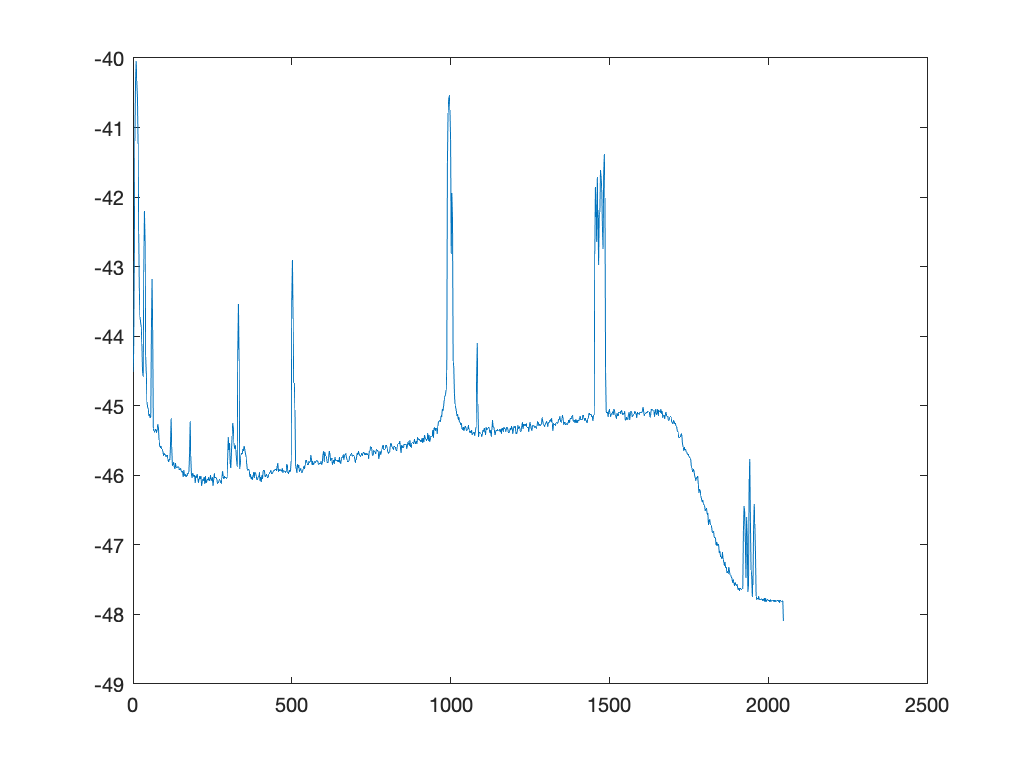

[pxx,f] = pwelch(hpDataVec,2048,[],[],samplFreq);
figure;
plot(f,log10(pxx));

We will only use the frequency range from the high-pass filter cutoff to 1.6 kHz (where GWOSC data has been low-passed already) to design the target transfer function.

whtnTF = ones(size(pxx));
%indices for frequency range
fRangeIndx = f>= fHi & f<=1.6e3;
%Target transfer function
whtnTF(fRangeIndx) = 1./sqrt(pxx(fRangeIndx));
%Filter order
whtnFltrOrdr = 1024;
wb = fir2(whtnFltrOrdr,f/(samplFreq/2), whtnTF);

We can plot the designed filter's transfer function magnitude to see if it looks alright.

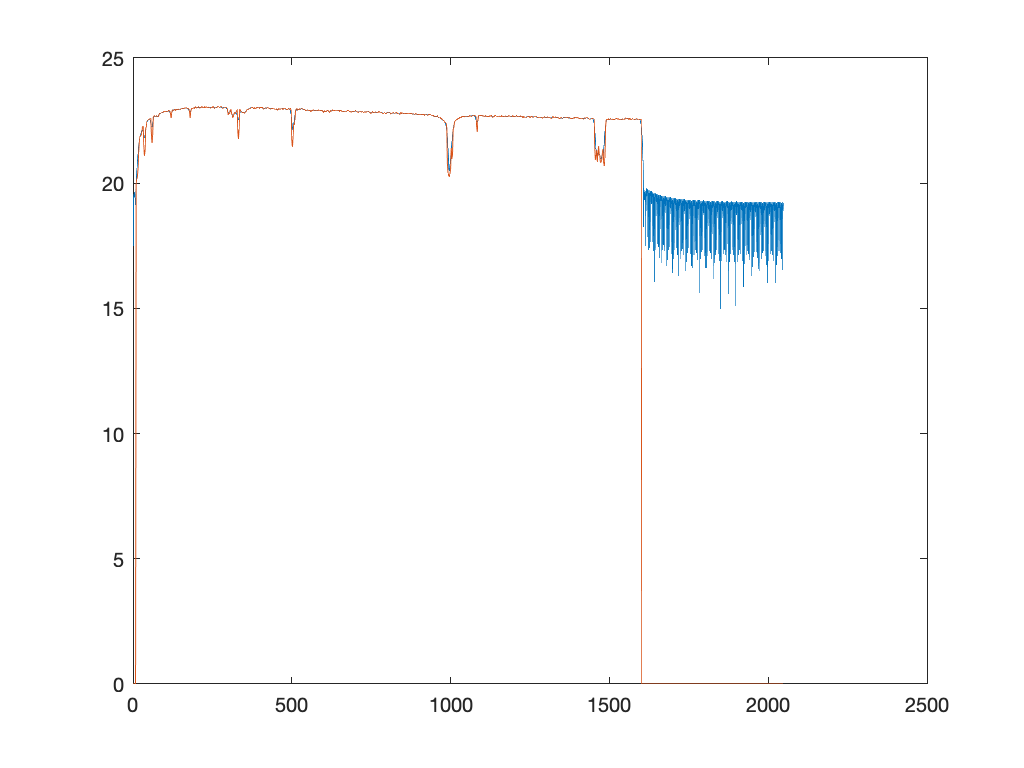

%Impulse sequence
impVec = zeros(1,nSamples);
impVec(floor(nSamples/4)) = 1;
%Impulse response
impResp = fftfilt(wb,impVec);
%Transfer function
trainWhtTF = abs(fft(impResp));
%Positive DFT frequencies
kNyq = floor(nSamples/2)+1;
posFreqDataVec = (0:(kNyq-1))/dataLen;
%Plot filter transfer function
figure;
plot(posFreqDataVec, log10(trainWhtTF(1:kNyq)));
hold on;
plot(f,log10(whtnTF));

Apply the whitening filter to the whole data and drop startup transient. 

whtDataVec = fftfilt(wb,dataVec);

Study the whitened data in different domains.

### Time series

tserFig = figure;
timeVec = (0:(nSamples-1))/samplFreq;
plot(timeVec,whtDataVec);

This plot shows a giant filter startup transient! We need to drop it.

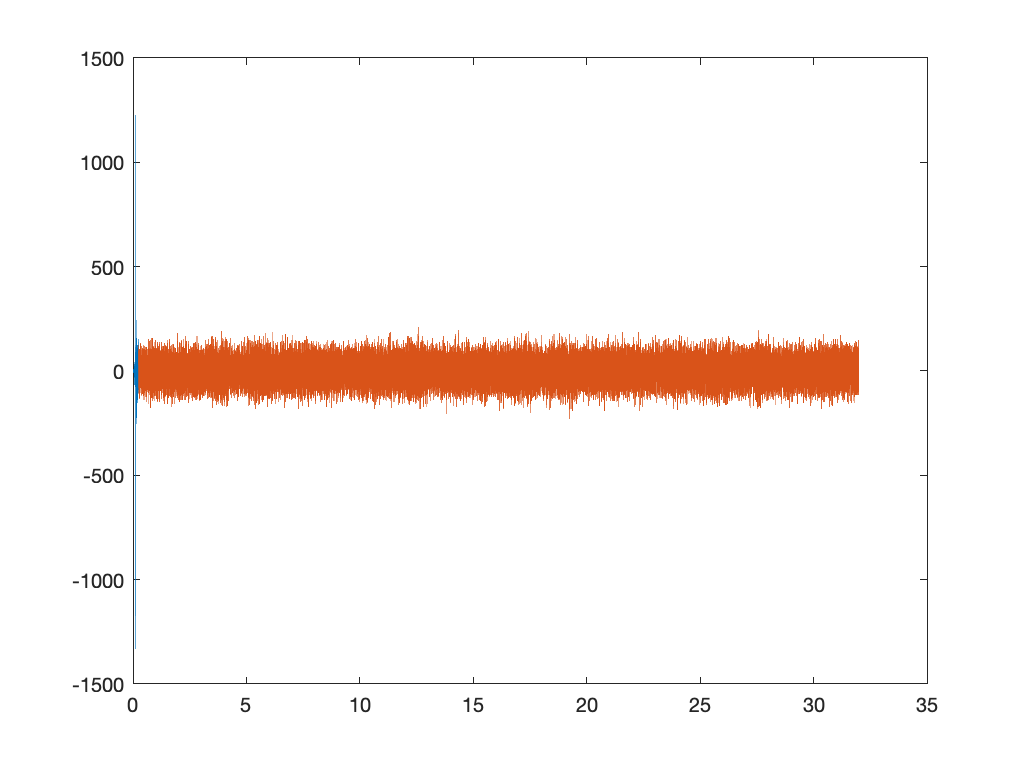

figure(tserFig);
hold on;
plot(timeVec((whtnFltrOrdr+1):end),whtDataVec((whtnFltrOrdr+1):end));

### Spectrum

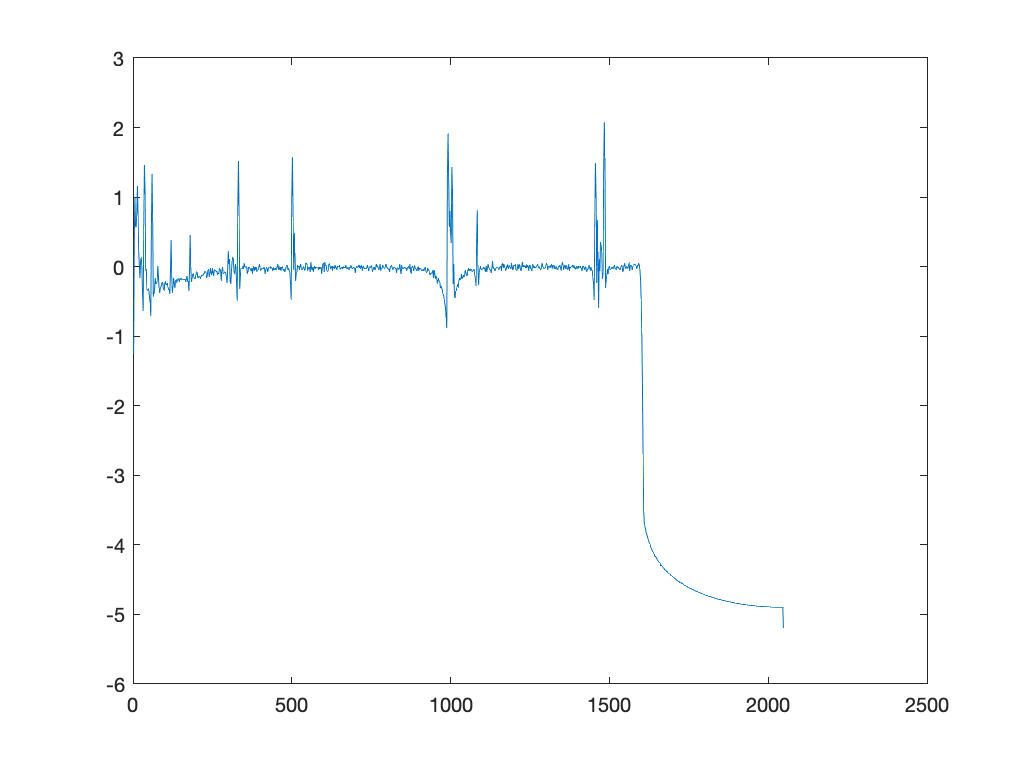

[pxxWD,freqVec] = pwelch(whtDataVec,2048,[],[],samplFreq);
figure;
plot(freqVec,log10(pxxWD));

### Spectrogram

Spectrogram of the data and the whitened data.

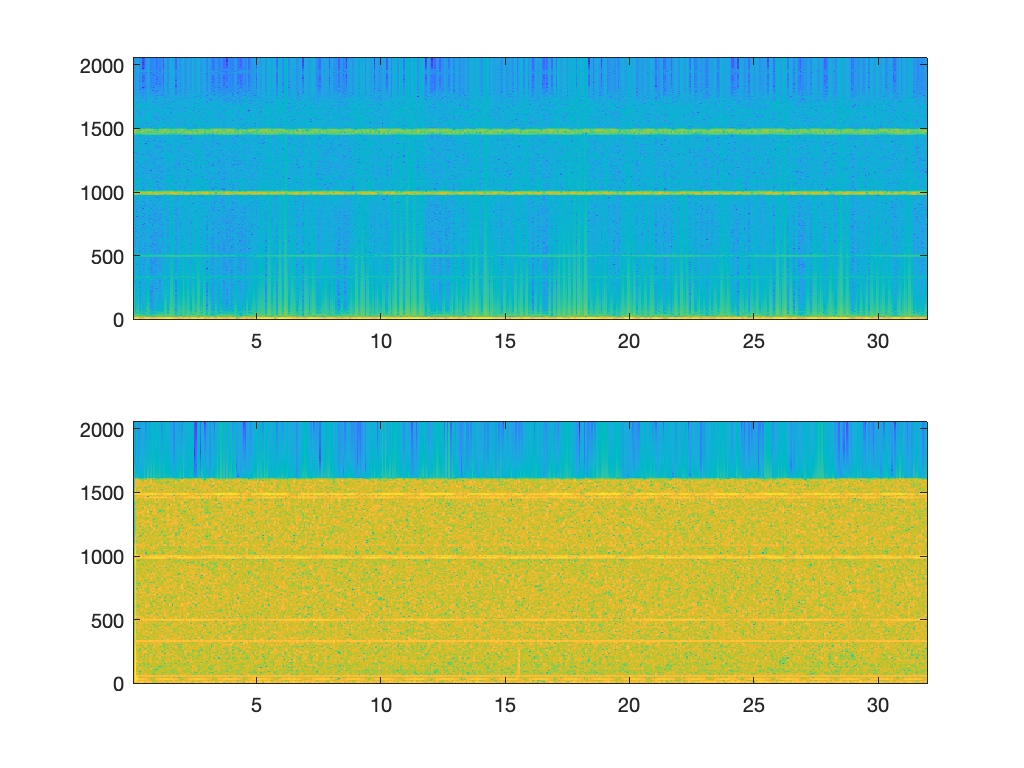

figure;
subplot(2,1,1);
[S,F,T]=spectrogram(dataVec,512,[],[],samplFreq);
imagesc(T,F,log10(abs(S))); axis xy;
subplot(2,1,2);
[S,F,T]=spectrogram(whtDataVec,512,[],[],samplFreq);
imagesc(T,F,log10(abs(S))); axis xy;